
% Характеристики объекта
u_lim = 2;
phi_lim = 0.2;
omega_lim = 0.3;
M=-10;
J=100;

% Область построения
phi_area=5

phi_area = 5

omega_area=1

omega_area = 1


scaler=1

scaler = 1


t=linspace(0,50,10e3);

scaler=scaler*0.5;
da=phi_area/scaler

da = 10

db=omega_area/scaler

db = 2

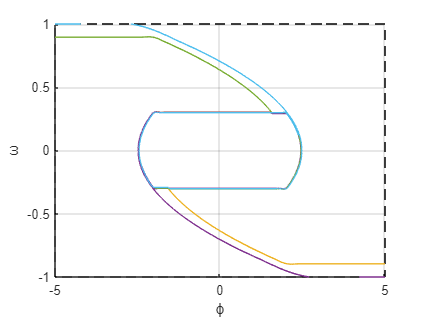


P=[-phi_area omega_area];
dP=[da 0
    0 -db
    -da 0
    0 db
    ];

close all
figure
hold on

for i=1:4
    for j=1:scaler*2
        P=[P;P(end,:)+dP(i,:)];
    end
end
grid on

plot(P(:,1),P(:,2),'--k')

for p=P'
    x0=flip(p');
    [~,y]=ode45(@(t,x) next(x,u_lim,phi_lim, omega_lim,J,M),t,x0);
    plt=plot(y(:,2),y(:,1));
    %scatter(x0(2),x0(1),"filled","MarkerFaceColor",plt.Color)
end

xlabel("\phi")
ylabel("\omega")

xlim(phi_area*[-1 1])
ylim(omega_area*[-1 1])

function y=next(x, u_lim, phi_lim, omega_lim,J,M)

% X=[omega; phi]
% Y=[dOmega/dt; dPhi/dt]



w = x(1);
phi = x(2);

% Зона нечувствительности ДУС
if abs(w) < omega_lim
    w=0;
end

% Зона нечувствительности датчика положения
if abs(phi) < phi_lim
    phi=0;
end

% Закон управления
u = phi - sign(w)* ( J * w^2 )/(2*M);
dw = (M/J)*sign(u);

% Зона нечувствительности по управлению
if abs(u) < u_lim
    dw=0;
end

y=[dw; x(1)];
end
